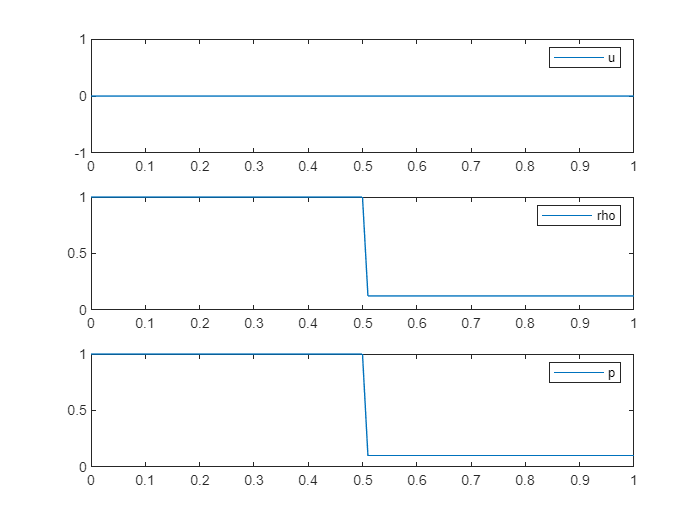

clear;clc;
dt = 0.001; % 时间推进的步长
dx = 0.01; % 空间离散的步长
msod = MySod(dx,0,0.5,1,dt,1.4);
msod.build(0,1,1,0,0.125,0.1);
msod.show(); % 展示初始条件

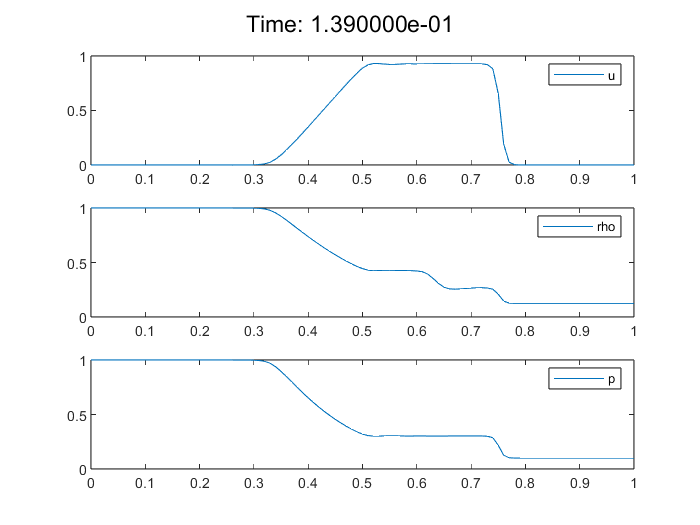

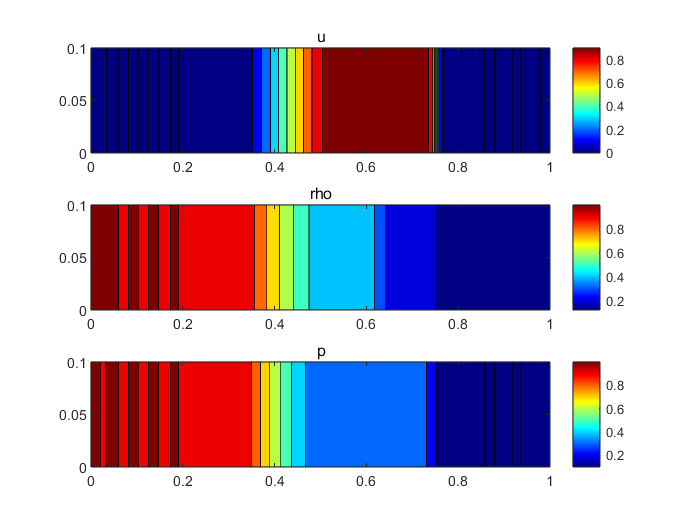

% 设置差分的方法
splitMethod = StegerWarming;
timeForward = RK3;
discreteMethod = WENO;

msod.setSplitMethod(splitMethod);
msod.setTimeForwardMethod(timeForward);
msod.setDiscreteMethod(discreteMethod);

% 采用差分方法推进到0.14s
idx = 0;
for i = 0:dt:0.14
    idx = idx + 1;
    msod.timeStep();
    if mod(idx,10) == 0 || idx == 1

        figure(1);
        sgtitle(sprintf('Time: %d',i));
        msod.show();

        % 二维展示
        figure(2);
        msod.show3d();

        pause(0.1);
    end
end

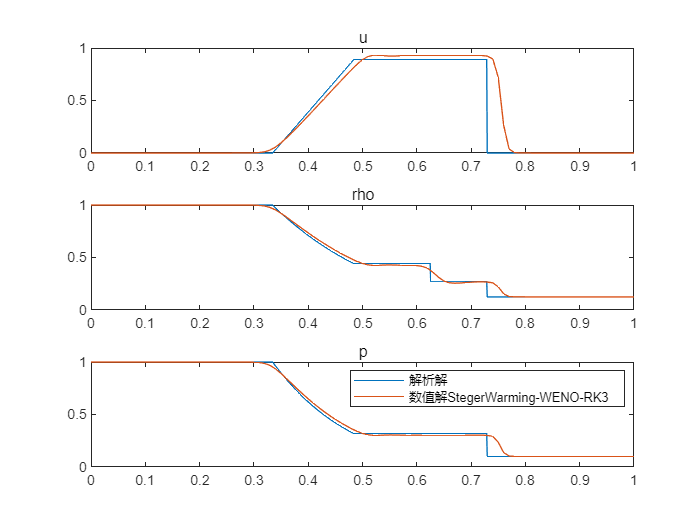

% 解析解
ref = analytic_sod(0.14);
ref.x = ref.x + 0.5; % 解析解中默认的坐标是[-0.5,0.5],需要平移

% 与解析解对比
subplot(311)
plot(ref.x,ref.u,msod.x,msod.u)
title('u')

subplot(312)
plot(ref.x,ref.rho,msod.x,msod.rho)
title('rho')

subplot(313)
plot(ref.x,ref.P,msod.x,msod.p)
title('p')

numerical_method = sprintf('数值解%s-%s-%s',class(splitMethod),class(discreteMethod),class(timeForward));
legend('解析解',numerical_method,Location='best')